% This exercise uses speksitIIR.m function from Mycourses. The function has
% to be in the same folder as this skript to work.
% You can write 'help speksitIIR' to  Command Window to get information
% about speksitIIR function. Sampling frequency in both sections is 48000Hz
% Use legend() to name each magnitude response clearly.
fs = 48000;

## Task a)

Design digital minimum order (lowest possible order) I) Butterworth, II) Chebyshev 1, III) and Elliptic high-pass filters that fulfill specs drawn on the figure(1) and plot them to figure(1). Helpful functions: butter, buttord, cheb1, cheb1ord, ellip, ellipord freqz.

### Go see what values `speksitIIR` takes to find out what to give for `*ord` functions!

### Easiest way to get correct frequency vector from `freqz` is to give it sample rate as an argument:

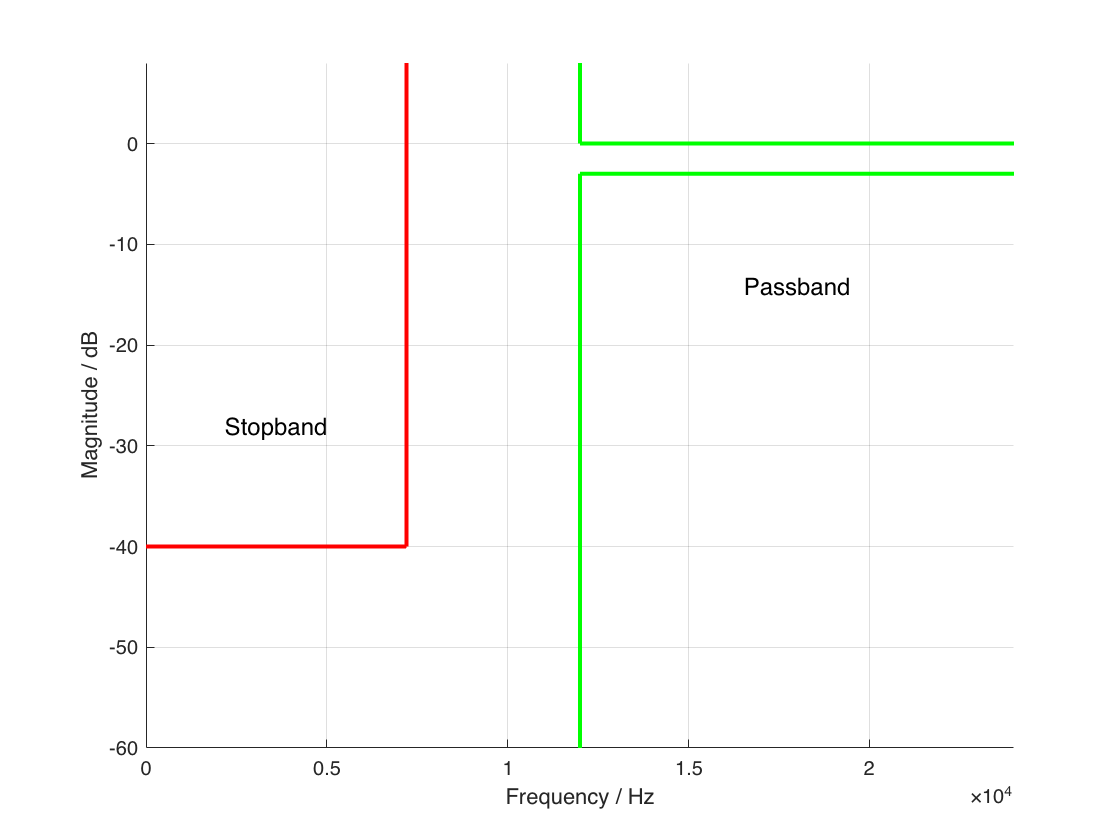

figure(1);clf
hold on

%plots here
[bb,ab] = butter(3,0.9,'high');
[Hb,w] = freqz(bb,ab,[],fs);

grid on
speksitIIR(0.5, 0.3, 3, 40, 'high', 48000);
hold off
%legend(___)
xlabel('Frequency / Hz')
ylabel('Magnitude / dB')

## Task b)

Design digital minimum order (lowest possible order) I) Butterworth, II) Chebyshev 1, III) and Elliptic band-pass filters that fulfill specs drawn on the figure(2) and plot them to figure(2). Helpful functions: butter, buttord, cheb1, cheb1ord, ellip, ellipord freqz.

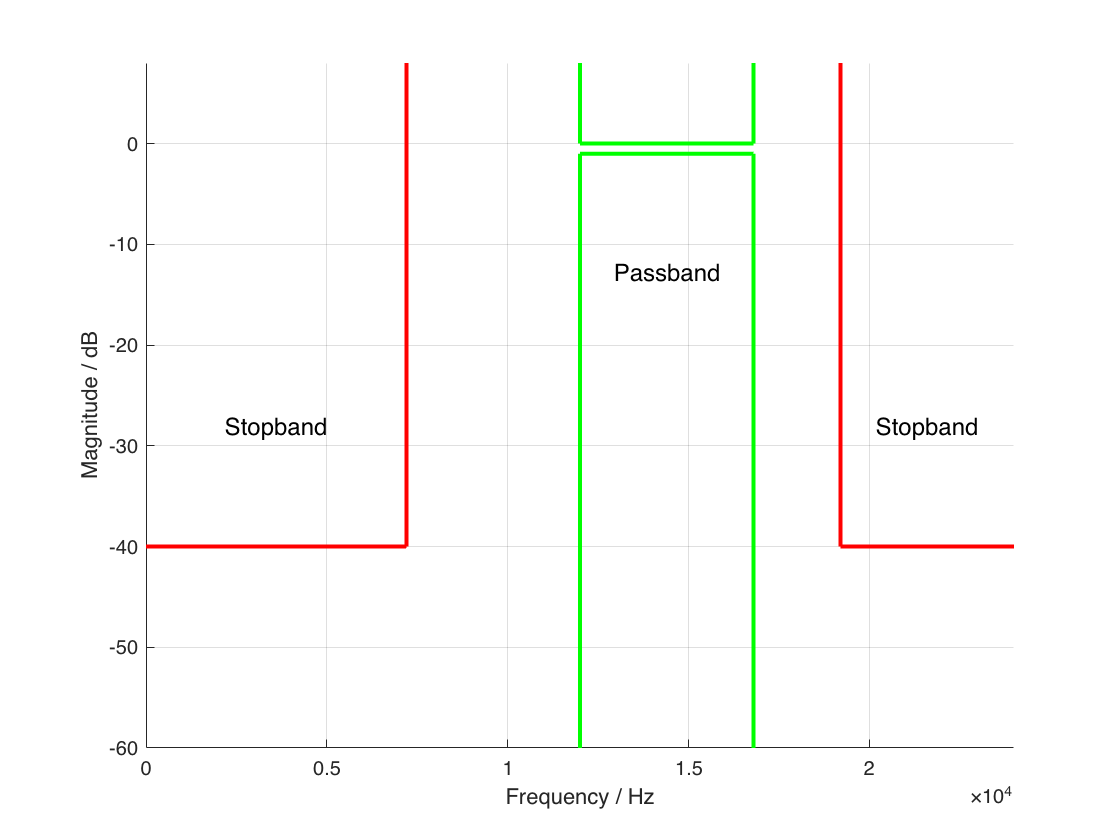

figure(2);clf
hold on

%plots here

grid on
speksitIIR([0.5 0.7], [0.3 0.8], 1, 40, '', 48000);
hold off
%legend(___)
xlabel('Frequency / Hz')
ylabel('Magnitude / dB')

## Task c)

What are the orders of each filters and what differences: butterworth, chebyshev 1 and elliptic filter have?